# Experimental Fits

## Load Data

Load Experimental Data

% 105 nm DNA contours
experimentalData_105 = importExperimentalData_105();

% 217/398/1023 nm DNA start sites and loop circumferences
experimentalData_217_398_1023 = importExperimentalData_217_398_1023();

Load Simulated Data

% 398 nm Multiloop start sites and loop circumferences
simulatedData_398 = importSimulatedData_398();

## Perform Simulations

1023 Spontaneous Looping Fits

% DNA properties

DNA.contourLength = 1023;
DNA.persistenceLength = 50;
DNA.numAgents = 0;
DNA.power = 0.01;
DNA.kPlanar = 0;
DNA.kLinear = 2;

% Condensing agent properties

AGENT.length = 3.4;
AGENT.radius = 0.30;
AGENT.power = 0.20;

% Simulation properties

SIM.power = 0.05;
SIM.numTrials = 100000;
SIM.displayEvolutions = false;
SIM.displayMolecules = false;
SIM.saveImages = false;

simulationData1023 = performSimulation(DNA, AGENT, SIM);

displaySSLC(simulationData1023, experimentalData_217_398_1023, DNA)

105 nm Unlooped DNA

% DNA properties

DNA.contourLength = 105;
DNA.persistenceLength = 120;

% Simulation properties

SIM.numTrials = 100;

simulationData105NoProt = performSimulation(DNA, AGENT, SIM);

105 nm Looped DNA

% DNA properties

DNA.numAgents = 6;

simulationData105WithProt = performSimulation(DNA, AGENT, SIM);

105 nm Plots

plotDNAProperties(experimentalData_105.prot0, experimentalData_105.prot2, 'Experimental')
plotDNAProperties(simulationData105NoProt.planarCoords, simulationData105WithProt.planarCoords, 'Simulated')

217 nm Single Loop

% DNA properties

DNA.contourLength = 217;
DNA.persistenceLength = 50;
DNA.numAgents = 18;
DNA.kPlanar = 0;
DNA.kLinear = 1;

% Simulation properties

SIM.numTrials = 100000;

simulationData217 = performSimulation(DNA, AGENT, SIM);

displaySSLC(simulationData217, experimentalData_217_398_1023, DNA)

398 Single Loop

% DNA properties

DNA.contourLength = 398;
DNA.numAgents = 12;

DNA

DNA = struct with fields:
        contourLength: 398
    persistenceLength: 50
            numAgents: 12
                power: 0.0100
              kPlanar: 0
              kLinear: 1


AGENT

AGENT = struct with fields:
    length: 3.4000
    radius: 0.3000
     power: 0.2000


SIM.numTrials = 1;
SIM.displayEvolutions = true;
SIM.displayMolecules = true

SIM = struct with fields:
                power: 0.0500
            numTrials: 1
    displayEvolutions: 1
     displayMolecules: 1
           saveImages: 0


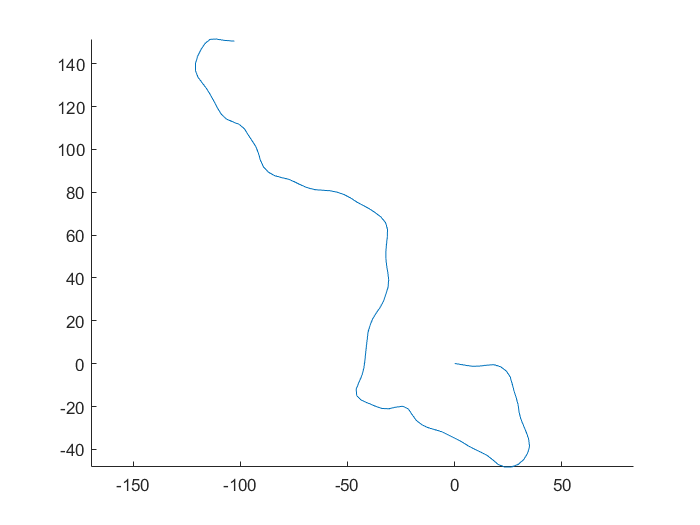

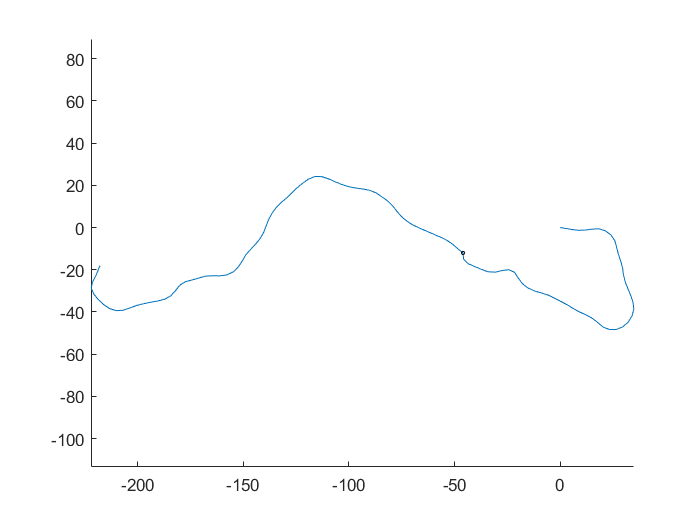

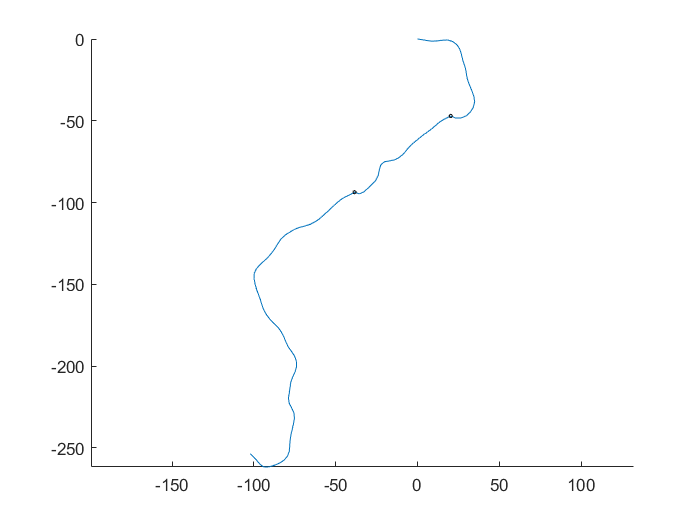

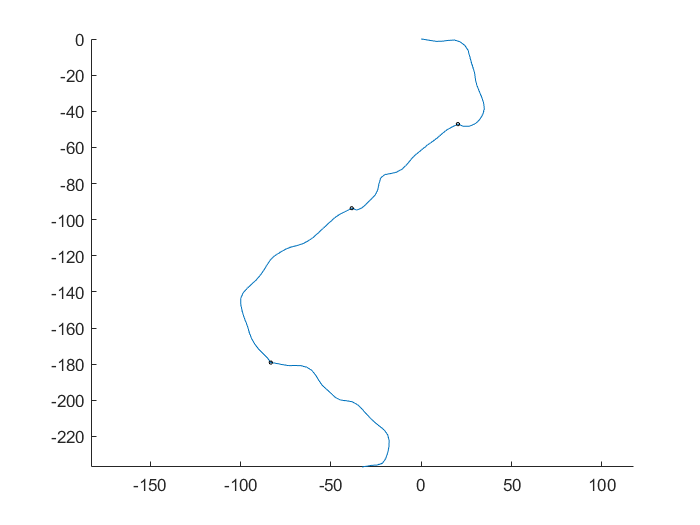

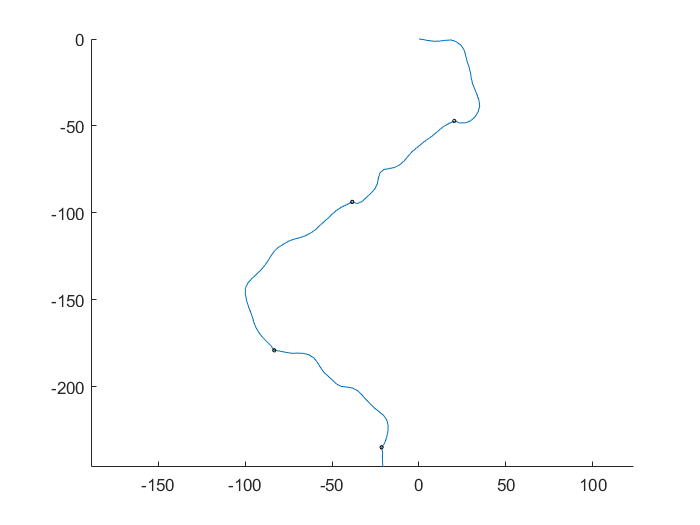

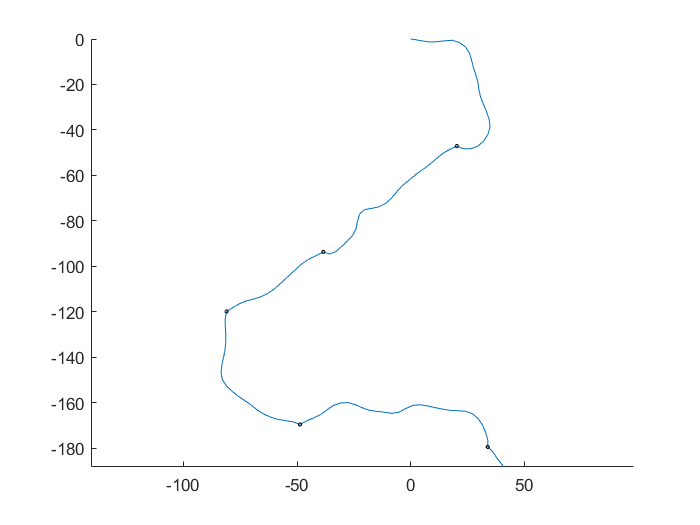

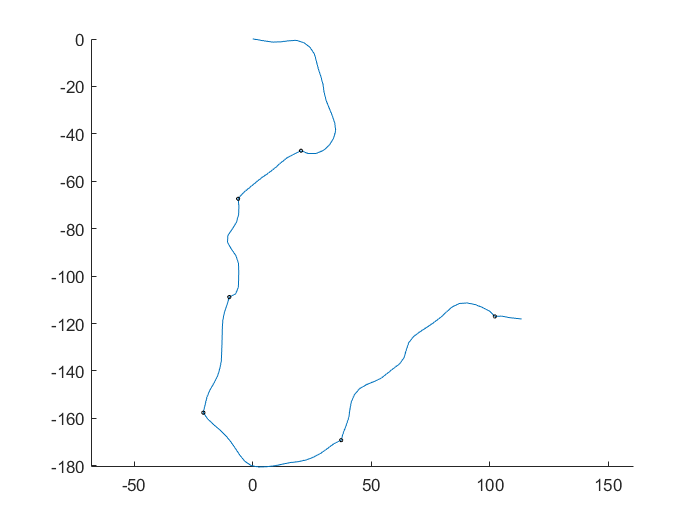

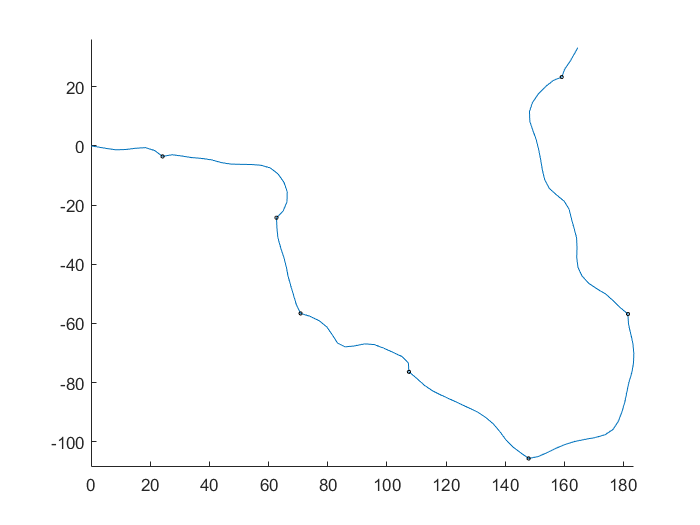

simulationData398 = performSimulation(DNA, AGENT, SIM);

displaySSLC(simulationData398, experimentalData_217_398_1023, DNA)

performSimulation(DNA, AGENT, SIM);

398 Multiloop

% DNA properties

DNA.numAgents = 25;

% Simulation properties

SIM.numTrials = 2000;
SIM.displayMolecules = true;
SIM.displayEvolutions = false;
SIM.saveImages = true;

% Set rng seed for reproducability
rng(398)

simulationData398Multilooped = performSimulation(DNA, AGENT, SIM);

sum(~isnan(simulatedData_398.Flower2Loop))

ans = 254

sum(~isnan(experimentalData_217_398_1023.startSites_398_2loop))

ans = 78


sum(~isnan(simulatedData_398.Flower3Loop))

ans = 302

sum(~isnan(experimentalData_217_398_1023.startSites_398_3loop))

ans = 42

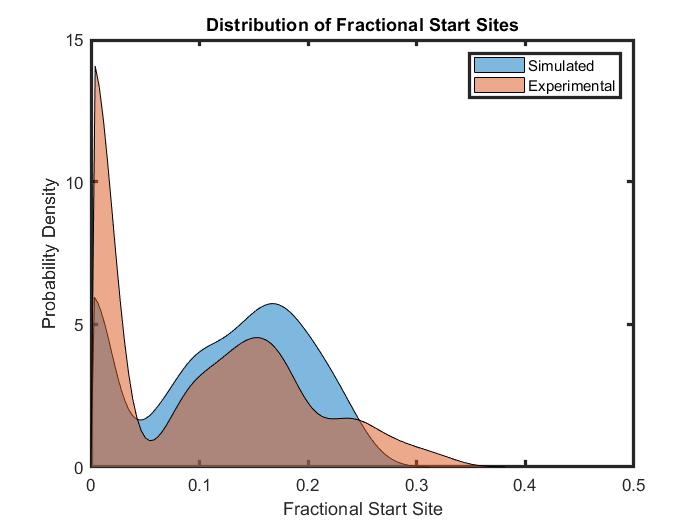

%   2 loop
%   Small allowance for KDE support bounds
    epsilon = 1e-10;
    
%   KDE bandwidth
    bandwidth = 0.02;

%   New figure
    figure
    hold on

%   Distribution of simulated start sites
    plotKDE(simulatedData_398.Flower2Loop/398, [-epsilon, 0.5+epsilon], bandwidth)

%   Distribution of experimental start sites
    plotKDE(experimentalData_217_398_1023.startSites_398_2loop, [-epsilon, 0.5+epsilon], bandwidth)

%   Title, etc.
    title('Distribution of Fractional Start Sites')
    ylabel('Probability Density')
    xlabel('Fractional Start Site')
    axis([0,0.5,0,15])
    xticks(0:0.1:0.5)
    yticks(0:5:15)
    legend({'Simulated', 'Experimental'})

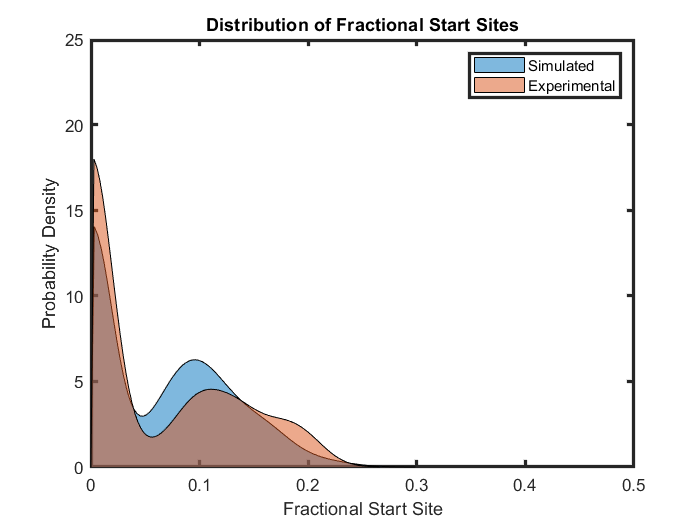

    
%   New figure
    figure
    hold on

%   Distribution of simulated start sites
    plotKDE(simulatedData_398.Flower3Loop/398, [-epsilon, 0.5+epsilon], bandwidth)

%   Distribution of experimental start sites
    plotKDE(experimentalData_217_398_1023.startSites_398_3loop, [-epsilon, 0.5+epsilon], bandwidth)

%   Title, etc.
    title('Distribution of Fractional Start Sites')
    ylabel('Probability Density')
    xlabel('Fractional Start Site')
    axis([0,0.5,0,25])
    xticks(0:0.1:0.5)
    yticks(0:5:25)
    legend({'Simulated', 'Experimental'})